disp("Independent work 09 - Monte Carlo method 01.");

Independent work 09 - Monte Carlo method 01.



clear all;
clc;

disp("Question 01.");

Question 01.



% Question 1: Monte Carlo simulation to estimate the area of 1/4 circle

% Parameters
A = [2, 4]; % coordinates of point A
B = [2, 8]; % coordinates of point B
disp(['Point A: (', num2str(A(1)), ', ', num2str(A(2)), ')']);

Point A: (2, 4)


disp(['Point B: (', num2str(B(1)), ', ', num2str(B(2)), ')']);

Point B: (2, 8)



% Equation of the quarter circle:
disp('Equation of 1/4 circle: (x - A(1))^2 + (y - A(2))^2 <= radius^2');

Equation of 1/4 circle: (x - A(1))^2 + (y - A(2))^2 <= radius^2


% Radius of the circle
radius = B(2) - A(2);
disp(['Radius of the circle: ', num2str(radius)]);

Radius of the circle: 4



% Number of random points
N = 10000;
disp(['Number of random points: ', num2str(N)]);

Number of random points: 10000



% Generate random points in the square
x_rand = A(1) + radius * rand(N, 1);
y_rand = A(2) + radius * rand(N, 1);

% Check if points are inside the 1/4 circle
inside_circle = (x_rand - A(1)).^2 + (y_rand - A(2)).^2 <= radius^2;

% Estimate the area of 1/4 circle
area_circle = sum(inside_circle) / N * radius^2;
disp(['Estimated area of 1/4 circle: ', num2str(area_circle)]);

Estimated area of 1/4 circle: 12.6256


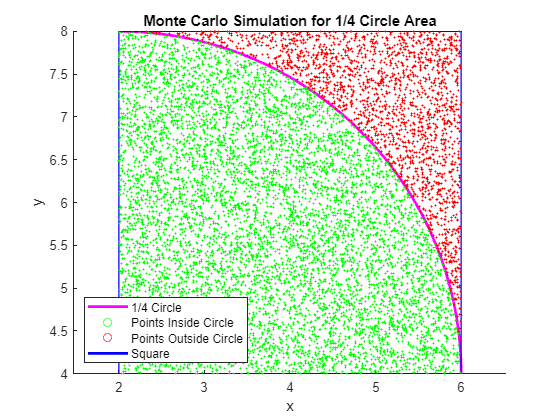


% Plotting
figure;
hold on;

% Plot the 1/4 circle
theta = linspace(0, pi/2, 100);
plot(A(1) + radius*cos(theta), A(2) + radius*sin(theta), 'm', 'LineWidth', 2); % 1/4 circle

% Create the rectangle (square) for the background
rectangle('Position', [A(1), A(2), radius, radius], 'EdgeColor', 'b'); % square

% Scatter the points
scatter(x_rand(inside_circle), y_rand(inside_circle), 1, 'g'); % points inside circle
scatter(x_rand(~inside_circle), y_rand(~inside_circle), 1, 'r'); % points outside circle

% Create a dummy plot for the "Square" legend entry (blue line)
plot(nan, nan, 'b', 'LineWidth', 2); % dummy blue line

% Add the legend
legend('1/4 Circle', 'Points Inside Circle', 'Points Outside Circle', 'Square', 'Location', 'SouthWest');

title('Monte Carlo Simulation for 1/4 Circle Area');
xlabel('x');
ylabel('y');
axis equal;
hold off;


disp("Question 02.");

Question 02.



% Question 2: Monte Carlo simulation to estimate the area under the curve and inside the ellipse

% Given function
f = @(x) 60 - 258*x + 146*x.^2 - 30*x.^3 + 2*x.^4;

% Display the function equation
disp('Function for curve: f(x) = 60 - 258*x + 146*x.^2 - 30*x.^3 + 2*x.^4');

Function for curve: f(x) = 60 - 258*x + 146*x.^2 - 30*x.^3 + 2*x.^4



% Ellipse equation parameters
xc = 5.5;
yc = -30;
a = sqrt(10);
b = sqrt(10);
ellipse_eq = @(x, y) ((x - xc).^2 / a^2 + (y - yc).^2 / b^2) <= 1;

% Display the ellipse equation
disp(['Ellipse equation: ((x - ', num2str(xc), ').^2 / ', num2str(a^2), ' + (y - ', num2str(yc), ').^2 / ', num2str(b^2), ') <= 1']);

Ellipse equation: ((x - 5.5).^2 / 10 + (y - -30).^2 / 10) <= 1



% Define the rectangular region
x_min = 0;
x_max = 11;
y_min = -155;
y_max = 0;

disp(['Rectangular region: x_min = ', num2str(x_min), ', x_max = ', num2str(x_max), ', y_min = ', num2str(y_min), ', y_max = ', num2str(y_max)]);

Rectangular region: x_min = 0, x_max = 11, y_min = -155, y_max = 0



% Number of random points
N = 10000;
disp(['Number of random points: ', num2str(N)]);

Number of random points: 10000



% Generate random points
x_rand = x_min + (x_max - x_min) * rand(N, 1);
y_rand = y_min + (y_max - y_min) * rand(N, 1);

% Check if points are inside the area under the curve
inside_curve = y_rand <= f(x_rand);
disp('Equation for points inside the curve: ');

Equation for points inside the curve: 


disp('y_rand <= f(x_rand) OR y <= f(x)');

y_rand <= f(x_rand) OR y <= f(x)



% Check if points are inside the ellipse
inside_ellipse = ellipse_eq(x_rand, y_rand);
disp('Equation for points inside the ellipse: ');

Equation for points inside the ellipse: 


disp('ellipse_eq(x_rand, y_rand) OR ((x - x_c)^2 / a^2 + (y - y_c)^2 / b^2) <= 1');

ellipse_eq(x_rand, y_rand) OR ((x - x_c)^2 / a^2 + (y - y_c)^2 / b^2) <= 1


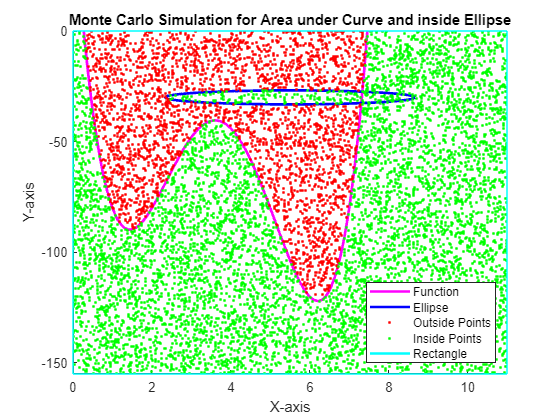


% Points inside the curve (green in first visualization)
inside_region_curve = inside_curve;

% Points outside the curve (red in first visualization)
outside_region_curve = ~inside_curve;

% Points inside the curve or inside the ellipse (green in second visualization)
inside_region_curve_or_ellipse = inside_curve | inside_ellipse;

% Points outside both the curve and the ellipse (red in second visualization)
outside_region_curve_and_ellipse = ~inside_region_curve_or_ellipse;

% % Visualization without ellipse (showing only the curve area)
% figure;
% hold on;
% fplot(f, [x_min, x_max], 'm', 'LineWidth', 2); % Plot function
% scatter(x_rand(outside_region_curve), y_rand(outside_region_curve), 'r.'); % Points outside curve
% scatter(x_rand(inside_region_curve), y_rand(inside_region_curve), 'g.'); % Points inside curve
% % Create the rectangle (blue) for the boundary
% rectangle('Position', [x_min, y_min, x_max-x_min, y_max-y_min], 'EdgeColor', 'c'); % blue rectangle
% % Create a dummy plot for the "Rectangle" legend entry (blue line)
% plot(nan, nan, 'c', 'LineWidth', 2); % dummy blue line
% title('Monte Carlo Simulation for Area under Curve without Ellipse');
% xlabel('X-axis');
% ylabel('Y-axis');
% legend('Function', 'Outside Points', 'Inside Points', 'Rectangle', 'Location', 'SouthEast');
% axis([x_min, x_max, y_min, y_max]);
% hold off;

% % Print significant variables
% disp(['Number of points inside the curve (green in first visualization): ', num2str(sum(inside_region_curve))]);
% disp(['Number of points outside the curve (red in first visualization): ', num2str(sum(outside_region_curve))]);

% Visualization with ellipse (showing both the curve and ellipse)
figure;
hold on;
fplot(f, [x_min, x_max], 'm', 'LineWidth', 2); % Plot function
theta = linspace(0, 2*pi, 100);
plot(xc + a*cos(theta), yc + b*sin(theta), 'b', 'LineWidth', 2); % Plot ellipse
scatter(x_rand(outside_region_curve_and_ellipse), y_rand(outside_region_curve_and_ellipse), 'r.'); % Points outside curve and ellipse
scatter(x_rand(inside_region_curve_or_ellipse), y_rand(inside_region_curve_or_ellipse), 'g.'); % Points inside curve or ellipse
% Create the rectangle (blue) for the boundary
rectangle('Position', [x_min, y_min, x_max-x_min, y_max-y_min], 'EdgeColor', 'c'); % blue rectangle
% Create a dummy plot for the "Rectangle" legend entry (blue line)
plot(nan, nan, 'c', 'LineWidth', 2); % dummy blue line
title('Monte Carlo Simulation for Area under Curve and inside Ellipse');
xlabel('X-axis');
ylabel('Y-axis');
legend('Function', 'Ellipse', 'Outside Points', 'Inside Points', 'Rectangle', 'Location', 'SouthEast');
axis([x_min, x_max, y_min, y_max]);
hold off;


% Print significant variables
disp(['Number of points inside the curve or inside the ellipse (green in second visualization): ', num2str(sum(inside_region_curve_or_ellipse))]);

Number of points inside the curve or inside the ellipse (green in second visualization): 7112


disp(['Number of points outside both the curve and the ellipse (red in second visualization): ', num2str(sum(outside_region_curve_and_ellipse))]);

Number of points outside both the curve and the ellipse (red in second visualization): 2888
